## Desarrollo y Codigo

### Ejercicio 

Extracción de Características con LBP para Clasificación de Texturas.

clc; clear; close all;
format short;

1. Descarga y organiza el conjunto de imágenes: Puedes utilizar el dataset clásico en análisis de texturas Brodatz Texture Dataset, el conjunto Flickr Material Database (FMD) o un conjunto personalizado distintas clases:

- corteza, ladrillo, burbujas, hierba, cuero, piel, rafia, arena, paja, agua, tejido, madera, lana

imds = imageDatastore('KTH_TIPS',...
    'IncludeSubfolders', true,...
    'LabelSource', 'foldernames');

2. Carga las imágenes y conviértelas a escala de grises: El Brodatz Texture Dataset original no incluye etiquetas categóricas. Sin embargo, existen versiones modificadas y extensiones del dataset que sí incluyen etiquetas o puedes asignar etiquetas basadas en la tabla de referencia.

imds.ReadFcn = @(loc)imresize(rgb2gray(imread(loc)), [200 200]);

3. Implementación de LBP El algoritmo LBP sigue estos pasos:

- Para cada píxel central, comparar su intensidad con 8 vecinos.

- Generar un patrón binario (1 si el vecino ≥ central, 0 en otro caso).

- Convertir el binario a decimal y reemplazar el píxel central.

numImages = numel(imds.Files);

radius = 2;          % Radio del vecindario
numNeighbors = 8;    % Número de puntos de muestreo
% numBins = 128; 

function lbp_image = computeLBP(image)
    [rows, cols] = size(image);
    lbp_image = zeros(rows-2, cols-2, 'uint8');
    
    for i = 2:rows-1
        for j = 2:cols-1
            center = image(i, j);
            % Comparar con sus 8 vecinos 
            neighbors = [image(i-1, j-1), image(i-1, j), image(i-1, j+1), ...
                         image(i, j+1),   image(i+1, j+1), image(i+1, j), ...
                         image(i+1, j-1), image(i, j-1)];
            
            binary_pattern = (neighbors >= center);
            % Convertir binario a decimal
            lbp_value = sum(binary_pattern .* 2.^(0:7)); 
            lbp_image(i-1, j-1) = lbp_value;
        end
    end
end

function features = extractLBPFeatures(images)
    num_images = numel(images.Files);
    features = zeros(num_images, 256);
    for k = 1:num_images
        lbp = computeLBP(readimage(images, k));
        hist = imhist(lbp, 256)';
        features(k, :) = hist / sum(hist); 
    end

end

4. Extracción de Características: Convertir cada imagen LBP en un histograma de 256 bins (para valores 0-255).

- Mostrar el histograma de una imagen individual.

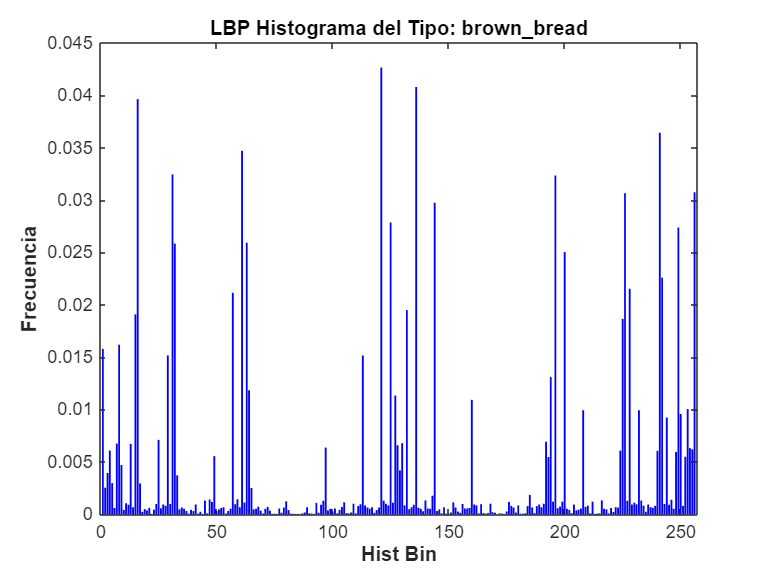

% Matriz de características
features = extractLBPFeatures(imds);
labels = imds.Labels;
data = array2table(features);
data.Label = labels;
histograma = table2array(data(83, 1:256));
figure;
bar(histograma, 'b');
xlabel('Hist Bin', 'FontWeight', 'bold');
ylabel('Frecuencia', 'FontWeight', 'bold');
title(['LBP Histograma del Tipo: ', char(labels(83))], 'Interpreter', 'none');

- Comparar histogramas por clase (ej. madera vs. tela vs. piedra).

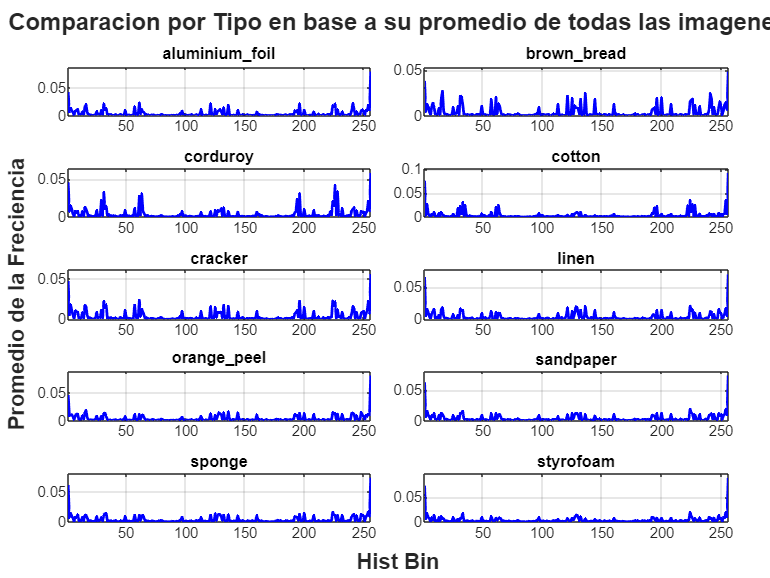

clases = categories(labels);
numClases = numel(clases);

figure;
t = tiledlayout(5, 2, 'Padding', 'compact', 'TileSpacing', 'compact');

for i = 1:numClases
    clase_actual = clases{i};
    
    idx = labels == clase_actual;
    
    % Extraer histogramas y promediar
    histogramas_clase = table2array(data(idx, 1:256));
    promedio_histograma = mean(histogramas_clase, 1);
    
    nexttile;
    plot(promedio_histograma, 'b', 'LineWidth', 1.5);
    title(strrep(clase_actual, '_', '\_'), 'Interpreter', 'tex');
    xlim([1, 256]);
    ylim([0, max(promedio_histograma)*1.1]);
    grid on;
end

% Etiquetas globales para los ejes
xlabel(t, 'Hist Bin', 'FontWeight', 'bold');
ylabel(t, 'Promedio de la Freciencia', 'FontWeight', 'bold');
sgtitle(t, 'Comparacion por Tipo en base a su promedio de todas las imagenes', 'FontWeight', 'bold');

5. Clasificación y Evaluación

- Divide los datos en entrenamiento (70 %) y prueba (30 %).

- Usa un modelo simple como vecinos más cercanos (k-NN) o Máquina de Soporte Vectorial (SVM) sobre los vectores de características y entrena el modelo.

- Calcula la exactitud en el conjunto de prueba.

- Visualiza las imágenes LBP para entender qué patrones se están detectando.

X = table2array(data(:, 1:256));
Y = labels;

Y_num = grp2idx(Y);

rng('default');  % Semilla
cv = cvpartition(Y_num, 'HoldOut', 0.3);
XTrain = X(cv.training, :);
YTrain = Y_num(cv.training);
XTest = X(cv.test, :);
YTest = Y_num(cv.test);
%SVM
template = templateSVM(...
    'Standardize', true,...
    'KernelFunction', 'linear',...
    'BoxConstraint', 1);

svmModel = fitcecoc(XTrain, YTrain,...
    'Learners', template,...
    'Coding', 'onevsall');

svmPred = predict(svmModel, XTest);
accuracySVM = sum(svmPred == YTest)/numel(YTest);
fprintf('Exactitud SVM: %.2f%%\n', accuracySVM*100);

Exactitud SVM: 93.83%


Veamos que cuenta con una alta precisión 

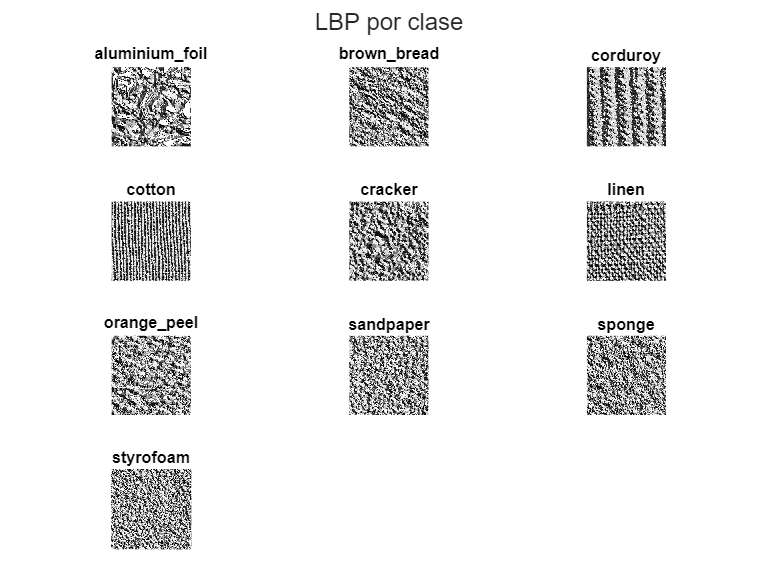

clases = categories(imds.Labels);
numClases = numel(clases);

figure;
tiledlayout(ceil(numClases / 3), 3, 'Padding', 'compact', 'TileSpacing', 'compact');

for i = 1:numClases
    clase = clases{i};
    
    % Encuentra el índice de la primera imagen de esa clase
    idx = find(imds.Labels == clase, 1);
    
    % Leer y procesar la imagen
    img = readimage(imds, idx);
    lbpImg = computeLBP(img);
    
    % Mostrar la imagen LBP
    nexttile;
    imshow(lbpImg, []);
    colormap(gca, 'gray');
    title(strrep(clase, '_', '\_'), 'Interpreter', 'tex');
end

sgtitle('LBP por clase');

6. Visualización de Resultados:

- Descripción de los pasos realizados:

1. Primero carge imágenes de diferentes clases de texturas desde una carpeta  estructurada, utilizando imageDatastore.

2. Despues convirti todas las imágenes a escala de grises y se redimensionaron a un tamaño fijo (200x200 píxeles) para normalizar la entrada.

3. Luego implemente el algoritmo Local Binary Pattern (LBP) manualmente, que consiste  en comparar la intensidad del píxel central con sus 8 vecinos para formar un  patrón binario y luego convertirlo a un valor decimal.

4. A partir de las imágenes LBP generadas, se extrajeron histogramas de 256 bins  como vectores de características representativos de la textura.

5. Despues utilice una Máquina de Soporte Vectorial (SVM) con kernel lineal como  clasificador. El conjunto de datos se dividió en 70% entrenamiento y 30% prueba.

6. Evalue el rendimiento del modelo obteniendo una medida de precisión, y se visualice histogramas promedio por clase para comparar la distribución de texturas entre categorías.

- Algunos resultados obtenidos

Veamos la matriz de difusion 

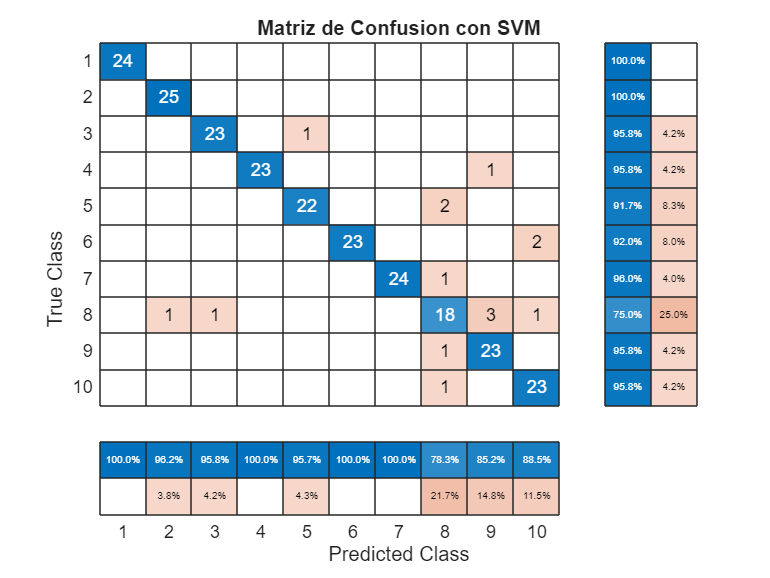

figure
confusionchart(YTest, svmPred,...
    'RowSummary', 'row-normalized',...
    'ColumnSummary', 'column-normalized',...
    'Title', 'Matriz de Confusion con SVM');

El modelo SVM tuvo un buen desempeño general al clasificar las texturas usando características LBP. La mayoría de las clases fueron correctamente clasificadas, especialmente las clases 1, 2, 3, 5 y 6, donde se alcanzaron tasas de precisión cercanas o iguales al 100%.

Sin embargo, también se pueden notar algunas confusiones entre clases visualmente similares. Por ejemplo:

- La clase 8 (en este caso, probablemente una textura más compleja o parecida a otras) tuvo una precisión más baja (78.3%), confundida principalmente con las clases 7 y 9.

- La clase 10 también fue levemente confundida con la clase 9.

- Las clases 5 y 6 tuvieron pequeñas confusiones (con 2 imágenes mal clasificadas cada una), lo que podría indicar texturas algo parecidas entre sí o poca variabilidad intra-clase.

En general, el modelo logró identificar correctamente la mayoría de las texturas, pero también queda claro que para algunas clases más parecidas entre sí, podría ser útil usar más características o modelos más complejos para reducir la confusión.

Ahora alplique PCA sobre los vectores de características LBP para reducir la dimensionalidad (de 256 a 2 dimensiones)  y visualizar la separación entre clases.

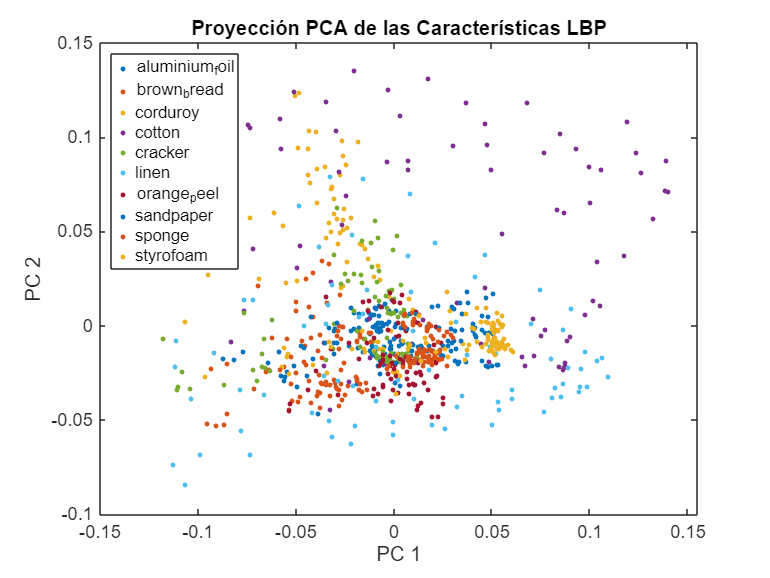

[coeff, score] = pca(X);
figure;
gscatter(score(:,1), score(:,2), Y);
title('Proyección PCA de las Características LBP');
xlabel('PC 1'); ylabel('PC 2');

En la gráfica se puede observar que algunas clases muestran una agrupación más definida (como "cotton" o "sandpaper"), lo que indica que sus patrones de textura son consistentes y distinguibles. Sin embargo, también hay superposición entre otras clases, especialmente en  la zona central, lo cual puede explicar por qué el modelo no alcanza una precisión perfecta: ciertas texturas comparten características similares.

La visualización PCA ayuda a entender mejor la capacidad de separación del  descriptor LBP y por lo que para mejorar la clasificación podrían combinarse otras técnicas o descriptores adicionales.

## Conclusiones

En esta práctica aprendi que con el descriptor Local Binary Pattern (LBP) a como extraer características de texturas y clasificar imágenes de distintos materiales. Desde el preprocesamiento de imágenes hasta la clasificación con SVM, pudimos comprobar cómo LBP captura patrones locales de textura bastante representativos.

La clasificación obtuvo una buena precisión, lo cual muestra que incluso un descriptor relativamente simple como LBP puede ser efectivo cuando se combina con modelos adecuados. Sin embargo, también notamos que algunas clases se mezclaban bastante, lo que vimos claramente en la proyección PCA. Esto indica que para ciertas texturas más complejas o parecidas, podría ser necesario combinar LBP con otros descriptores o técnicas más avanzadas.

En general, la experiencia fue útil para entender todo el flujo de trabajo en reconocimiento de texturas: desde la carga y preparación de datos, pasando por la extracción de características, hasta la clasificación y análisis de resultados. Además, visualizaciones como los histogramas promedio o la proyección PCA nos ayudaron a interpretar lo que realmente está aprendiendo el modelo.

## Referencias

- González, R., Woods, R., *Digital Image Processing*, Prentice Hall, 2008.

- Pratt, W. K., *Digital Image Processing*, John Wiley and Sons Inc, 2001.

- Jahne, B., *Digital Image Processing*, Springer, 2005.

- Sánchez Garreta, Josep Salvador; García, Vicente. *Special Issue on Data Preprocessing in Pattern Recognition: Recent Progress, Trends and Applications, 2002.* 